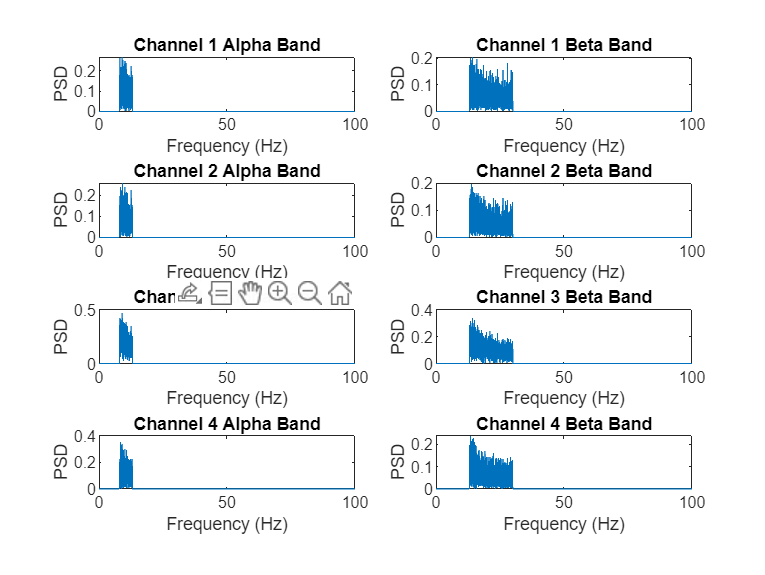

% Assuming 'data' is your matrix with channels as columns
% Sample data generation (replace this with your actual data)
Fs = 200; % Sampling frequency
t = 0:1/Fs:1-1/Fs; % Time vector for 1 second
% data = [sin(2*pi*10*t)' sin(2*pi*20*t)' cos(2*pi*15*t)' sin(2*pi*25*t)']; % Replace with your data
dataset = load('../Datasets/EEG/EEG_Viktor-Left_side_electrode_cluster_ch1-green_ch2-yellow_ch3-orange_ch4-red_2023-12-21_142419.txt');
data = dataset(:,1:4);
% Assuming your matrix is named 'data'
labels = dataset(:, 5); % Extract labels from column 5

% Split data based on labels
data_label_0 = dataset(labels == 0, :);
data_label_1 = dataset(labels == 1, :);% Define alpha and beta frequency ranges
alphaRange = [8 13];
betaRange = [13 30];

% Number of points for FFT
n = size(data_label_0, 1);
f = Fs*(0:(n/2))/n; % Frequency bins

% Pre-allocate arrays for PSDs
alphaPSDs = zeros(length(f), 4);
betaPSDs = zeros(length(f), 4);

for i = 1:4 % Iterate through the first four channels
    % Perform FFT
    fftChannel = fft(data_label_0(:,i));
    
    % Calculate the Power Spectral Density
    P2 = abs(fftChannel/n);
    P1 = P2(1:n/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    % Extract alpha and beta frequencies
    alphaIndices = f >= alphaRange(1) & f <= alphaRange(2);
    betaIndices = f >= betaRange(1) & f <= betaRange(2);

    % Store alpha and beta PSDs
    alphaPSDs(:,i) = P1;
    alphaPSDs(~alphaIndices,i) = 0; % Zero out non-alpha frequencies
    betaPSDs(:,i) = P1;
    betaPSDs(~betaIndices,i) = 0; % Zero out non-beta frequencies
end

% Plotting
figure;
for i = 1:4
    subplot(4,2,2*i-1);
    plot(f, alphaPSDs(:,i));
    title(['Channel ', num2str(i), ' Alpha Band']);
    xlabel('Frequency (Hz)');
    ylabel('PSD');
    
    subplot(4,2,2*i);
    plot(f, betaPSDs(:,i));
    title(['Channel ', num2str(i), ' Beta Band']);
    xlabel('Frequency (Hz)');
    ylabel('PSD');
end

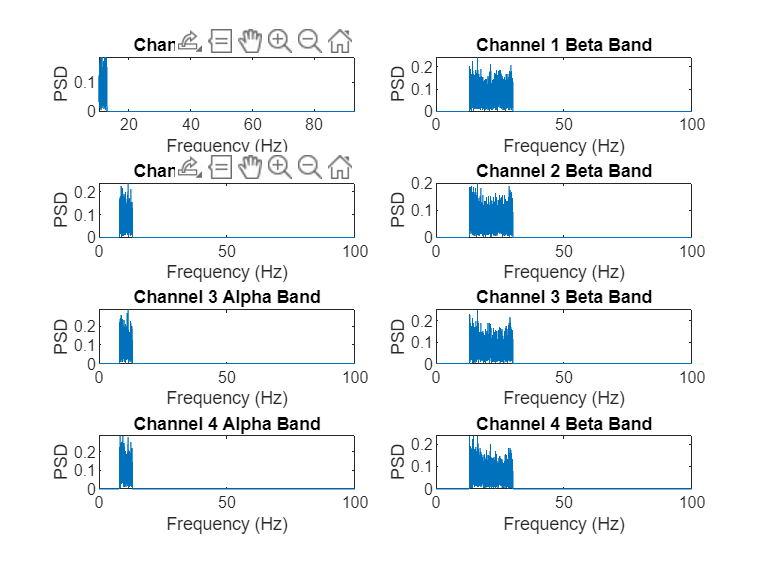



for i = 1:4 % Iterate through the first four channels
    % Perform FFT
    fftChannel = fft(data_label_1(:,i));
    
    % Calculate the Power Spectral Density
    P2 = abs(fftChannel/n);
    P1 = P2(1:n/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    % Extract alpha and beta frequencies
    alphaIndices = f >= alphaRange(1) & f <= alphaRange(2);
    betaIndices = f >= betaRange(1) & f <= betaRange(2);

    % Store alpha and beta PSDs
    alphaPSDs(:,i) = P1;
    alphaPSDs(~alphaIndices,i) = 0; % Zero out non-alpha frequencies
    betaPSDs(:,i) = P1;
    betaPSDs(~betaIndices,i) = 0; % Zero out non-beta frequencies
end

% Plotting
figure;
for i = 1:4
    subplot(4,2,2*i-1);
    plot(f, alphaPSDs(:,i));
    title(['Channel ', num2str(i), ' Alpha Band']);
    xlabel('Frequency (Hz)');
    ylabel('PSD');
    
    subplot(4,2,2*i);
    plot(f, betaPSDs(:,i));
    title(['Channel ', num2str(i), ' Beta Band']);
    xlabel('Frequency (Hz)');
    ylabel('PSD');
end